# Initialize

global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 4e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0;
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;

singleFilterPlot = nFilters; 


### Loop

n_loops = 1;

for iter = 1:n_loops
    n_plot = 0;


### Variances

    %% Ql %%
    Ql_sigma = 0.377; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0.27;% .* Ql_target ./ 500; % Relative variance of f0, normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = Ql_target - 1.5 .* Ql_target .* Ql_sigma;
    
    %%%% Scattered design parameters %%%%
    Ql_scattered = Ql_target + Ql_sigma .* randn(1,nFilters);
    Ql_scattered(Ql_scattered < Ql_min_thresh) = Ql_min_thresh;
    df = f0 ./ Ql_target;
    f0_scattered = f0 + df .* f0_sigma .* randn(1,nFilters);

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,f0_scattered,Z0_thru,Z0_KID,Ql_scattered,Qi,ThruLineLosses,sep,singleFilterPlot);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 12.835919 seconds


    
    % showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 5.536149 seconds
Usable Spectral Fraction = 0.89
Section took 3.166501 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,f0_scattered,Z0_thru,Z0_KID,Ql_scattered,Qi,ThruLineLosses,sep,singleFilterPlot);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 10.323121 seconds


    
    % showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 5.401204 seconds
Usable Spectral Fraction = 0.81
Section took 2.885998 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,f0_scattered,Z0_thru,Z0_KID,Ql_scattered,Qi,ThruLineLosses,sep,singleFilterPlot);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 7.891000 seconds


    
    % showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 5.298967 seconds
Usable Spectral Fraction = 0.85
Section took 2.886985 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

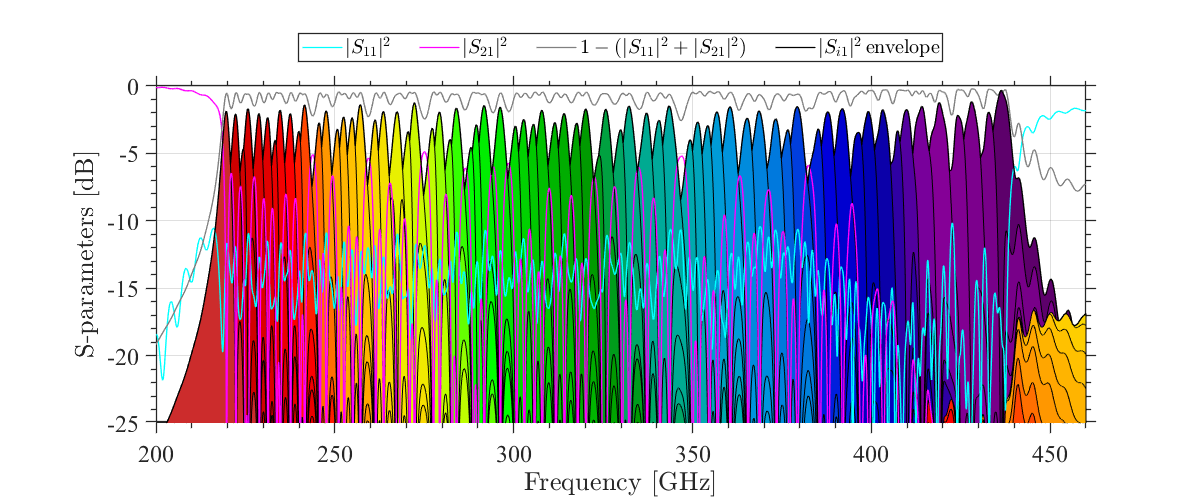

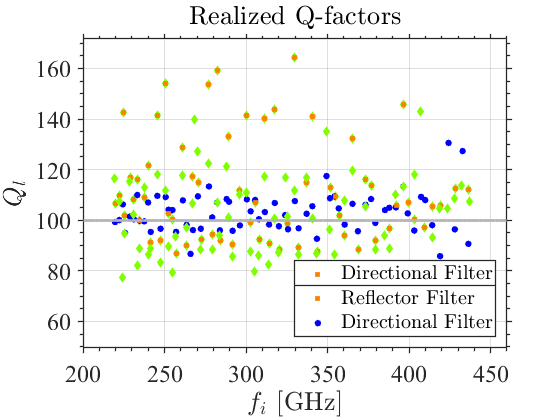

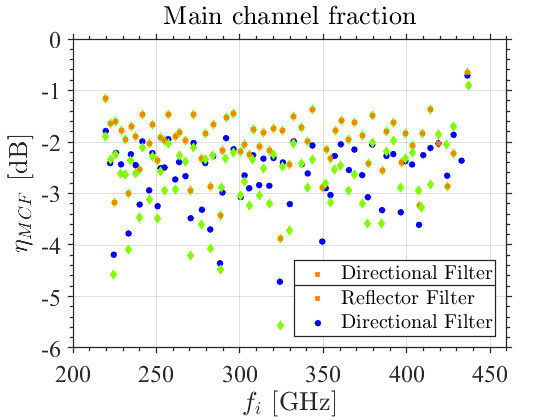

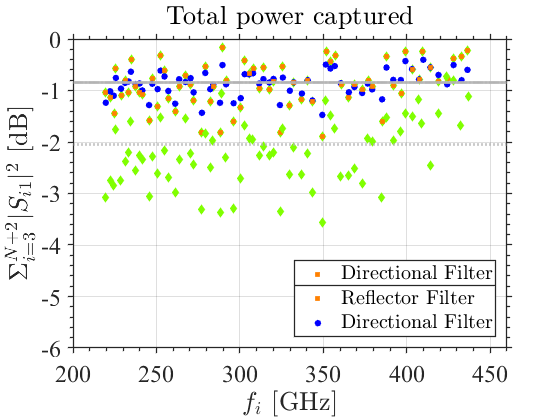

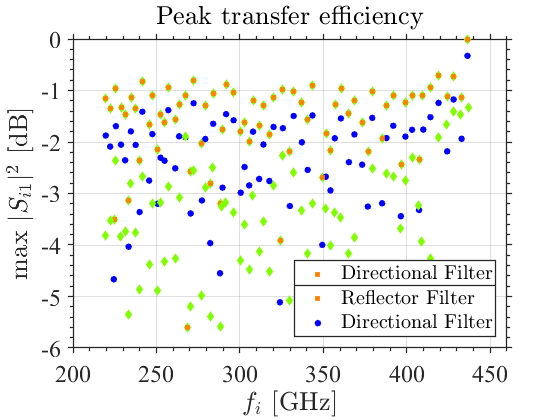

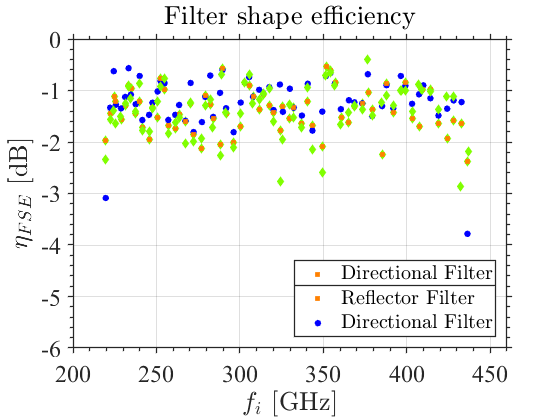

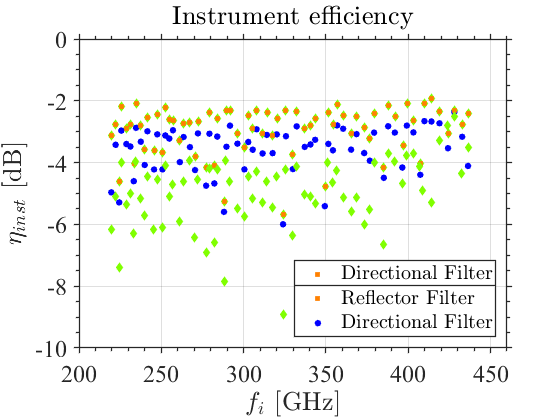

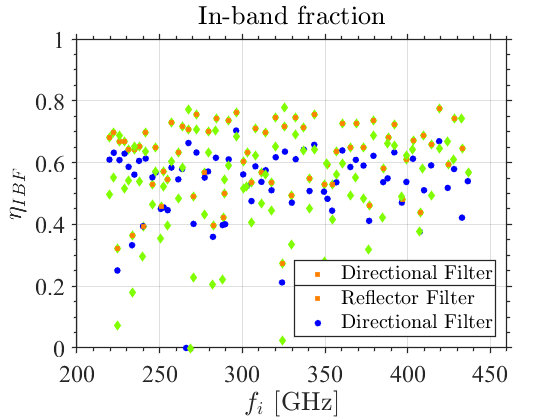

n_plot = 1;
showFilterBank(f,Data_dir);
showMetrics(f,Ql_target,Data_dir);

n_plot = 2;
showFilterBank(f,Data_refl);
showMetrics(f,Ql_target,Data_refl);

n_plot = 3;
showFilterBank(f,Data_man);
showMetrics(f,Ql_target,Data_man);


formatPlotting();